## 交报告用

clc;clear all;close all;
location = '6.15/';
file = 'rx';
filename = [file, '.mat'];
load([location, filename]);
[FrameNum, ChirpNum, RxNum, SampleNum] = size(mergedData);

## 3、参数导入

% 初始参数
p = setRadarParameters();
axis_info = setaxis(p);
axis_info.time = (1:FrameNum) * p.frameTime; 
% 裁剪
UsefulSampleNum = find(axis_info.range>p.rangecut, 1);
axis_info.range(UsefulSampleNum:end) = [];
UsefulChirpNumF = find(axis_info.velocity<-p.velocitycut, 1, 'last');
UsefulChirpNumL = find(axis_info.velocity>p.velocitycut, 1, "first");
axis_info.velocity([1:UsefulChirpNumF, UsefulChirpNumL:p.Chirps * p.Nfft]) = [];

## 4、算法

% 1dfft
ifft1dData = ifft(mergedData, [], 4);
fft1dData = fft1dwindow(ifft1dData, p.fft1dwindowType, p.Nfft);

1dfft done.


fft1dData(:,:,:,UsefulSampleNum:end) = [];
% MTI
MTIdata = MTI(fft1dData, p.MTIType);

Mean Cancellation done.


% 2dfft
fft2dData = fft2dwindow(MTIdata, p.fft2dwindowType, p.Nfft);

2dfft done.


fft2dData(:,[1:UsefulChirpNumF, UsefulChirpNumL:p.Chirps * p.Nfft],:,:) = [];
% NCA
NCAdata = squeeze(sum(fft2dData, 3));
% AAC
AACdata = applyAmplitudeCompensation(NCAdata);

AAC done.


% DN
DNdata = DenoisingRD(p.lossR, p.lossD, axis_info, AACdata);

Denoising done.


% GSMD峰值检测
dataNca = DNdata;
% 获取检测数据
cfarIdx = processCFARDetection(p.N_target, p.suppressWin, p.energyThresh, p.epsilon, p.minPts, DNdata);

% DOA estimate
DoA = estimateDoA(cfarIdx, p, fft2dData);
% Position modeling
observations = PositionModel(cfarIdx, axis_info, DoA(:, 2));

% 多径消除滤波
windowsize = 3;
observations_filterd = [];
for i = 1:size(observations, 1) - windowsize
    observationswindow = observations(i:i+windowsize, :);
    observations_filterd = [observations_filterd; mutlpathfilt(observationswindow, p)];
end
observations = unique(observations_filterd, 'rows');

% 帧关联
observations_related = slidingWindowClustering_offline(p.related_FrameNum, observations, p.epsilon1, p.minPoints1);
detections = cell(FrameNum, 1);
for k = 1:length(observations_related)
    idx = observations_related(k, 1);
    % 提取位置和速度 [x, y, vx, vy]
    pos_vel = [observations_related(k, 2), observations_related(k, 3), observations_related(k, 4)/10, observations_related(k, 5)/10];
    detections{idx} = [detections{idx}; pos_vel];
end

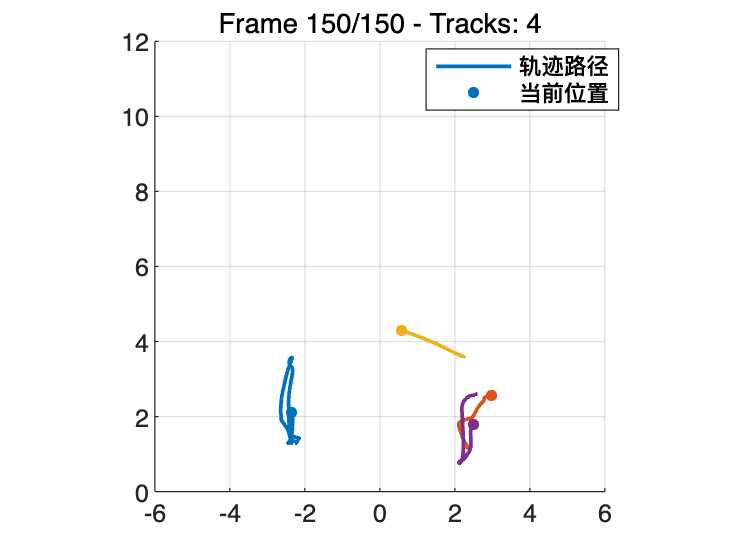

% 轨迹展示
figure;
axis equal;
grid on;
hold on;
xlim([-6 6]);ylim([0 12])
% 初始化轨迹历史容器
historyMap = containers.Map('KeyType', 'double', 'ValueType', 'any');
lineHandles = containers.Map('KeyType', 'double', 'ValueType', 'any'); % 存储线条句柄
pointHandles = containers.Map('KeyType', 'double', 'ValueType', 'any'); % 存储点句柄
% 设置颜色循环
colorOrder = get(gca, 'ColorOrder');
colorIndex = 1;
for i = 1:FrameNum
    % 更新轨迹点
    current_points = tracks_1f_plus(detections{i}, p.costThreshold, p.predictionframe, p.reset);
    % 更新轨迹历史并绘图
    for j = 1:size(current_points, 1)
        trackID = current_points(j, 1);
        position = current_points(j, 2:3);
        % 更新轨迹历史
        if isKey(historyMap, trackID)
            % 追加新位置
            historyMap(trackID) = [historyMap(trackID); position];
        else
            % 新建轨迹
            historyMap(trackID) = position;
            % 为新轨迹分配颜色
            lineHandles(trackID) = plot(NaN, NaN, ...
                'Color', colorOrder(colorIndex, :), ...
                'LineWidth', 1.5);
            pointHandles(trackID) = plot(NaN, NaN, 'o', ...
                'Color', colorOrder(colorIndex, :), ...
                'MarkerFaceColor', colorOrder(colorIndex, :), ...
                'MarkerSize', 4);
            % 更新颜色索引
            colorIndex = mod(colorIndex, size(colorOrder, 1)) + 1;
        end
        % 更新图形
        path = historyMap(trackID);
        set(lineHandles(trackID), 'XData', path(:,1), 'YData', path(:,2));
        set(pointHandles(trackID), 'XData', path(end,1), 'YData', path(end,2));
    end
    % 刷新图形
    title(sprintf('Frame %d/%d - Tracks: %d', i, FrameNum, historyMap.Count));
    drawnow;
    % 可选：控制帧率
    % pause(0.05); 
end
% 添加图例
legend('轨迹路径', '当前位置', 'Location', 'best');
hold off;